
clc,clear

% 输入判断矩阵
A = [1 2 3 5
    1/2 1 1/2 2
    1/3 2 1 2
    1/5 1/2 1/2 1];


## 一致性检验

根据输入的判断矩阵，求出最大特征值，计算一致性比例CR，来判断是否通过一致性检验

% eig求出矩阵特征值。max求最大值
maxlam = max(eig(A))

maxlam = 4.1128

[~,n]=size(A)       % 评价指标个数，就是A的行数。A是方阵，行数列数一样

n = 4

RI=[0,0,0.58,0.9,1.12,1.24,1.32,1.41,1.45];
CI=(maxlam-n)/(n-1)

CI = 0.0376

CR=CI/RI(n)

CR = 0.0418

if CR<0.10 %如果误差小于0.1则可以接受
    disp('该矩阵通过一致性检验。');
else
    disp('该矩阵未通过一致性检验！');
    return      % 终止运行
end

该矩阵通过一致性检验。


## 算术平均法求权重

% 归一化处理
[n,~]=size(A);      % 判断矩阵A是方阵，返回行数n即评价指标个数
Asum=sum(A,1);      % 按列求和  
Aprogress=A./(ones(n,1)*Asum); 

%每一行分别求和，求和的结果除以𝑛，得到的列向量就是权重向量
W=sum(Aprogress,2)./n;          

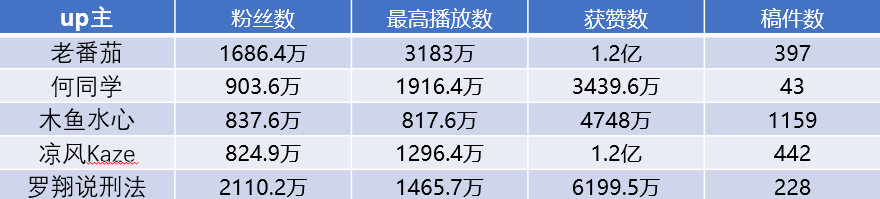

代入原始数据并初始化，每项指标乘以权重后相加（数据矩阵乘以权重向量），求出最终得分：

% 输入原始数据
% 注意，要确保同一列的数据单位相同！！！
data = [1686.4 3183 12000 397
        903.6 1916.4 3439.6 43
        837.6 817.6 4748 1159
        824.9 1296.4 12000 442
        2110.2 1465.7 6199.5 228]; 

% 归一化处理
[mm,nn]=size(data);     % 数据行数和列数
for j=1:nn  % 针对每一列
    msum=sum(data(:,j));     % 求这一列元素之和
    for i=1:mm      % 针对每一行
        data(i,j)=data(i,j)./msum;      % 每个元素的值都除以所在列的元素之和
    end
    
end

% 数据矩阵乘以权重列向量
% 也就是综合评分=0.49粉丝数+0.18播放数+0.23获赞数+0.1稿件数
grade = data*W

grade =     0.2858
    0.1322
    0.1599
    0.1820
    0.2401


%本文件出自b站/公众号：数学建模BOOM
% 关注公众号：数学建模BOOM，回复"购买"
% 获取全套视频课程+配套PPT课件+代码文件+完善售后服务+后续课程更新
% 版权所有，侵权必究。本文件仅供购买者学习使用，不得随意传播，否则为侵权行为